%% CONTROL PID PARA EL SISTEMA DE DOS TANQUES ACOPLADOS
% Este script:
% 1. Carga los parámetros guardados en parametros_tanques.mat
% 2. Construye la planta G(s)
% 3. Diseña un controlador PID con pidtune
% 4. Cierra el lazo
% 5. Grafica la respuesta del nivel
% 6. Compara lazo abierto y lazo cerrado
% 7. Calcula y grafica la señal de control en L/h
% 8. Muestra información de desempeño

clear; clc; close all;

%% 1) CARGAR PARÁMETROS DEL SISTEMA
if ~isfile('parametros_tanques.mat')
    error(['No se encontró el archivo parametros_tanques.mat. ' ...
           'Primero ejecuta el Live Script de cálculo de R1 y R2.']);
end

load('parametros_tanques.mat');

if ~exist('R1','var') || ~exist('R2','var') || ~exist('A_tanque','var')
    error('Faltan variables necesarias en parametros_tanques.mat');
end

A = A_tanque;

%% 2) CONSTRUIR LA PLANTA
% Función de transferencia de la planta:
% G(s) = H2(s) / Qin(s)

numG = 1;
denG = [A^2*R1, A*(2 + R1/R2), 1/R2];

G = tf(numG, denG);

fprintf('=====================================================\n');

fprintf('   CONTROL PID - SISTEMA DE DOS TANQUES ACOPLADOS\n');

   CONTROL PID - SISTEMA DE DOS TANQUES ACOPLADOS


fprintf('=====================================================\n');

fprintf('Área del tanque A = %.6f m^2\n', A);

Área del tanque A = 0.022500 m^2


fprintf('R1 = %.6f s/m^2\n', R1);

R1 = 722.630956 s/m^2


fprintf('R2 = %.6f s/m^2\n', R2);

R2 = 1013.846545 s/m^2


fprintf('=====================================================\n\n');


disp('Planta G(s) = H2(s)/Qin(s):');

Planta G(s) = H2(s)/Qin(s):


G


G =
 
                  1
  ----------------------------------
  0.3658 s^2 + 0.06104 s + 0.0009863
 
Continuous-time transfer function.



%% 3) DEFINIR REFERENCIA
href = 0.10;   % [m] -> 5 cm

%% 4) DEFINIR OBJETIVO DE DISEÑO
Ts_obj = 5;      % tiempo de establecimiento deseado [s]
zeta   = 0.7;    % amortiguamiento deseado
wn_obj = 4/(zeta*Ts_obj);

fprintf('Objetivo de diseño:\n');

Objetivo de diseño:


fprintf('Referencia = %.3f m\n', href);

Referencia = 0.100 m


fprintf('Tiempo de establecimiento deseado = %.2f s\n', Ts_obj);

Tiempo de establecimiento deseado = 5.00 s


fprintf('Amortiguamiento asumido = %.2f\n', zeta);

Amortiguamiento asumido = 0.70


fprintf('Frecuencia objetivo wn = %.6f rad/s\n\n', wn_obj);

Frecuencia objetivo wn = 1.142857 rad/s




%% 5) DISEÑO DEL CONTROLADOR PID
C = pidtune(G,'PID',wn_obj);

disp('Controlador PID obtenido con pidtune:');

Controlador PID obtenido con pidtune:


C


C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.186, Ki = 0.0169, Kd = 0.402
 
Continuous-time PID controller in parallel form.



Kp = C.Kp;
Ki = C.Ki;
Kd = C.Kd;

fprintf('Parámetros del PID:\n');

Parámetros del PID:


fprintf('Kp = %.8f\n', Kp);

Kp = 0.18642357


fprintf('Ki = %.8f\n', Ki);

Ki = 0.01693571


fprintf('Kd = %.8f\n\n', Kd);

Kd = 0.40180898




%% 6) SISTEMA EN LAZO CERRADO
% T(s) = C(s)G(s) / (1 + C(s)G(s))

T = feedback(C*G,1);

disp('Función de transferencia del sistema en lazo cerrado T(s):');

Función de transferencia del sistema en lazo cerrado T(s):


T


T =
 
        0.4018 s^2 + 0.1864 s + 0.01694
  --------------------------------------------
  0.3658 s^3 + 0.4628 s^2 + 0.1874 s + 0.01694
 
Continuous-time transfer function.


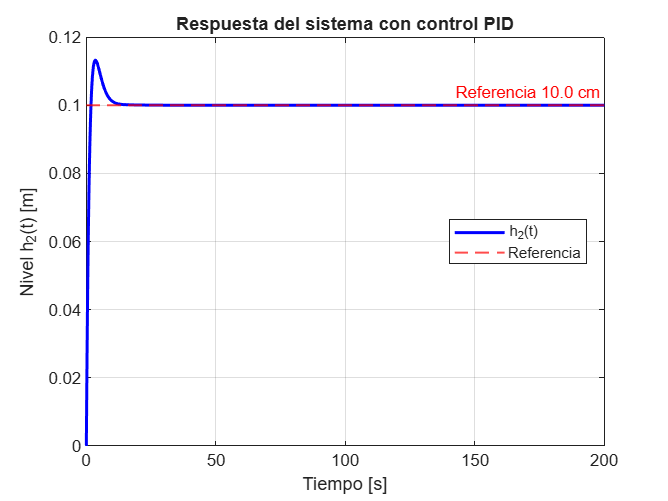


%% 7) RESPUESTA DEL SISTEMA A LA REFERENCIA
t = 0:0.1:200;

[y_unit, t_out] = step(T, t);
y_ref = href * y_unit;

figure;
plot(t_out, y_ref, 'b', 'LineWidth', 1.8); hold on;
texto_ref = sprintf('Referencia %.1f cm', href*100);
yline(href, '--r', texto_ref, 'LineWidth', 1.2);
grid on;
title('Respuesta del sistema con control PID');
xlabel('Tiempo [s]');
ylabel('Nivel h_2(t) [m]');
legend('h_2(t)', 'Referencia', 'Location', 'best');


%% 8) INFORMACIÓN DE DESEMPEÑO
info = stepinfo(href*T);

disp('Información de desempeño:');

Información de desempeño:


disp(info);

         RiseTime: 1.3093
    TransientTime: 8.9132
     SettlingTime: 8.9132
      SettlingMin: 0.0916
      SettlingMax: 0.1132
        Overshoot: 13.2399
       Undershoot: 0
             Peak: 0.1132
         PeakTime: 3.4744




%% 9) COMPARACIÓN CON LAZO ABIERTO
% Para comparar, usamos un caudal constante razonable

Qmax_Lh = 240;                       % [L/h]
Qmax = (Qmax_Lh/1000)/3600;          % [m^3/s]
fraccion_caudal = 0.70;              % 70% del caudal máximo
Qin_constante = fraccion_caudal * Qmax;

fprintf('Comparación con lazo abierto:\n');

Comparación con lazo abierto:


fprintf('Caudal máximo asumido = %.8e m^3/s\n', Qmax);

Caudal máximo asumido = 6.66666667e-05 m^3/s


fprintf('Fracción usada        = %.2f\n', fraccion_caudal);

Fracción usada        = 0.70


fprintf('Caudal aplicado Qin   = %.8e m^3/s\n\n', Qin_constante);

Caudal aplicado Qin   = 4.66666667e-05 m^3/s



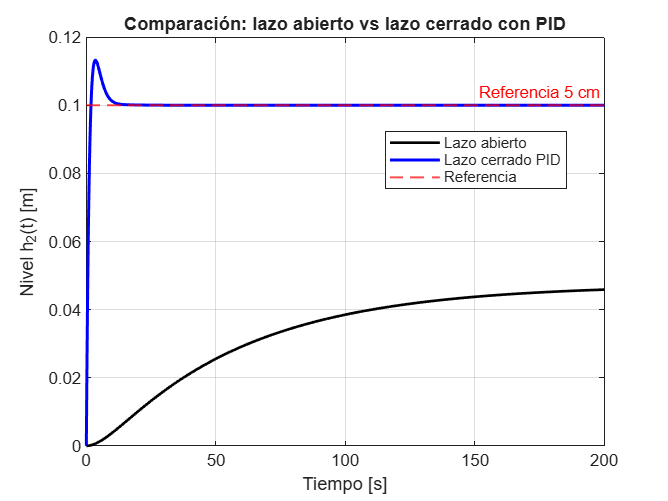


u_abierto = Qin_constante * ones(size(t));
[y_abierto, t_abierto] = lsim(G, u_abierto, t);

figure;
plot(t_abierto, y_abierto, 'k', 'LineWidth', 1.6); hold on;
plot(t_out, y_ref, 'b', 'LineWidth', 1.8);
yline(href, '--r', 'Referencia 5 cm', 'LineWidth', 1.2);
grid on;
title('Comparación: lazo abierto vs lazo cerrado con PID');
xlabel('Tiempo [s]');
ylabel('Nivel h_2(t) [m]');
legend('Lazo abierto', 'Lazo cerrado PID', 'Referencia', 'Location', 'best');

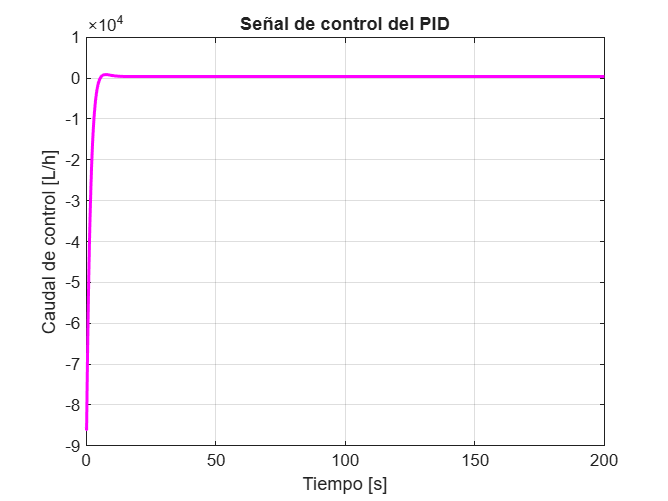


%% 10) SEÑAL DE CONTROL
% Se calcula a partir del error:
% u(t) = Kp*e(t) + Ki*integral(e) + Kd*derivada(e)

e = href - y_ref;   % error [m]

dt = t_out(2) - t_out(1);

% Integral del error
e_int = cumtrapz(t_out, e);

% Derivada del error
e_der = gradient(e, dt);

% Señal de control del PID
u_control = Kp*e + Ki*e_int + Kd*e_der;   % [m^3/s]

% Convertir a L/h para visualización más intuitiva
u_control_Lh = u_control * 3600 * 1000;

figure;
plot(t_out, u_control_Lh, 'm', 'LineWidth', 1.8);
grid on;
title('Señal de control del PID');
xlabel('Tiempo [s]');
ylabel('Caudal de control [L/h]');


%% 11) VALOR FINAL DE LA SEÑAL DE CONTROL
u_final = u_control(end);
u_final_Lh = u_control_Lh(end);

fprintf('Valor final de la señal de control:\n');

Valor final de la señal de control:


fprintf('u_final = %.8e m^3/s\n', u_final);

u_final = 1.00184218e-04 m^3/s


fprintf('u_final = %.4f L/h\n\n', u_final_Lh);

u_final = 360.6632 L/h




%% 12) ERROR FINAL DE SEGUIMIENTO
error_final = href - y_ref(end);

fprintf('Error final de seguimiento:\n');

Error final de seguimiento:


fprintf('error_final = %.8e m\n', error_final);

error_final = -1.35447209e-14 m


fprintf('error_final = %.4f cm\n\n', error_final*100);

error_final = -0.0000 cm



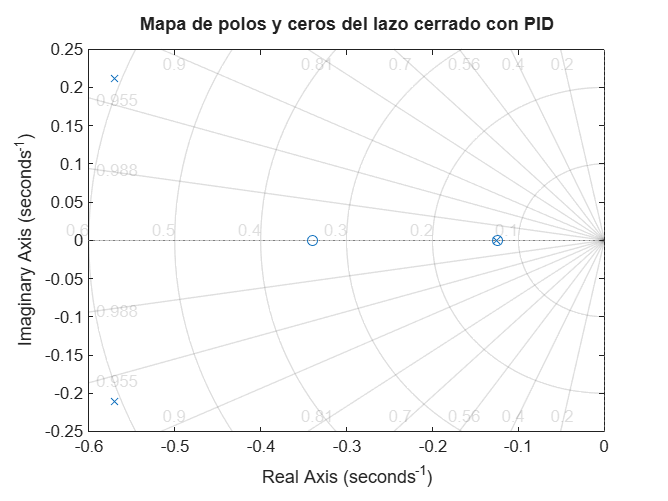


%% 13) MAPA DE POLOS Y CEROS DEL LAZO CERRADO
figure;
pzmap(T);
grid on;
title('Mapa de polos y ceros del lazo cerrado con PID');

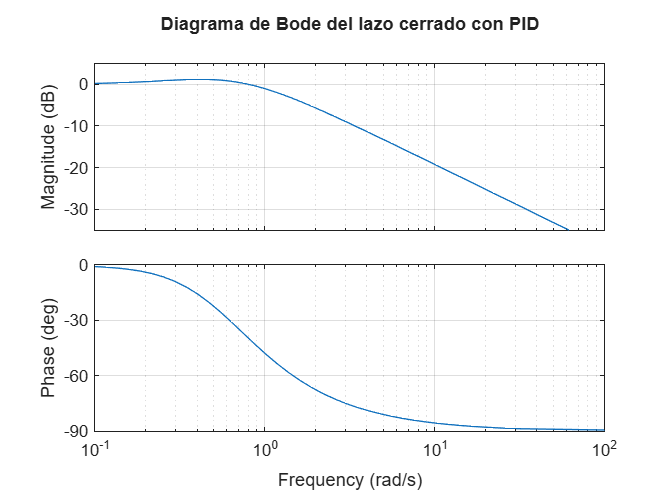


%% 14) DIAGRAMA DE BODE DEL LAZO CERRADO
figure;
bode(T);
grid on;
title('Diagrama de Bode del lazo cerrado con PID');